# Модулятор

# Single Sideband Suppressed Carrier 

# (AM-SSB-SC)

**Для запуска скриптов необходимо корневую папку репозитория сделать рабочей папкой Matlab!**

### 1. Введение

Одним из недостатков, присущих методу обычной амплитудной модуляции, явялеся удвоение требуемой полосы передачи по сравнению с полосой информационного ссобщения. Это удвоение излишне, так как спектр сигнала симметричен относительно частоты несущей, поэтому половина спектра уже несет в себе всю информацию о передаваемом сообщении.  Это можно увидеть на спектраграммах представленных в DSB TC Transmitter и DSB SC Transmitter. Амплитудная модуляция, которая не приводит к увеличению полосы сигнала, называется однополосной модуляцией (SSB - Sibgle Side Band). Обычная модуляция по этой причине иногда называется модуляция с удвоенной полосой (DSB - Double Side Band). Рассмотрим устройство модулятораЮ формирующего однополосный сигнал.

### 2. Однотональная модуляция с использованием полосового фильтра

Рассмотрение начнем с простейшего случая однотональной модуляции, при котором информационное сообщение представляет из себя гармонический сигнал вида: 

$m\left(t\right)=A_m \cos \left(2\pi f_m t\right)$,

где $A_m$ - амплитуда тона, $f_m$ - частота в герцах. 

Если мы просто смешаем это сообщение с несущей, две гармоники сигнала на несущей частоте, хотя сам сигнал состоит всего из одного тона. Это можно увидеть, если умножить сигнал на несущую и затем воспользоваться формулой произведения косинусов:


$$s_{\textrm{am}} \left(t\right)=A_m \cos \left(2\pi f_m t\right)\cdot A_c \cos \left(2\pi f_c t\right)=$$
 


$$=\frac{A_m A_c }{2}\left\lbrack \cos \left(2\pi \left(f_m +f_c \right)t\right)+\cos \left(2\pi \left(f_m -f_c \right)t\right)\right\rbrack \ldotp$$


Один из простейший способов формирования однополосного сигнала заключается в использовании полосового фильтра для удаления лишней половины спектра. Схема передающего устройства имеет вид:

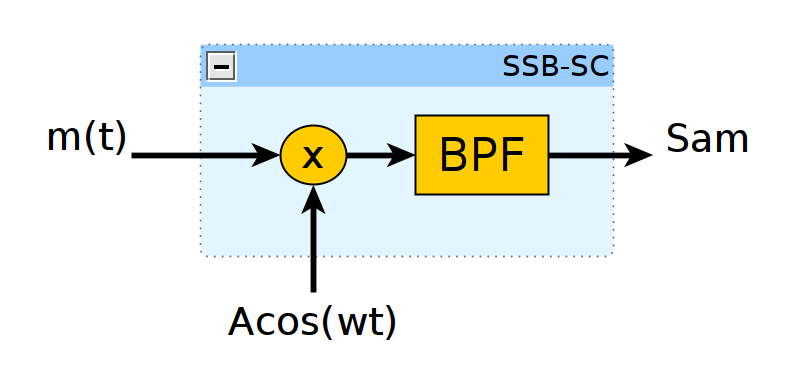

Если удаляется верхняя половина, то сигнал называется Lower Side Band (LSB). В случае однотональной модуляции LSB сигнал будет иметь вид:


$$s_{\textrm{LSB}} \left(t\right)=\frac{A_m A_c }{2}\cos \left(2\pi \left(f_m -f_c \right)t\right)\ldotp$$


Если удаляется нижняя половина спектра, то сигнал называется Upper Side Band (USB). В случае однотональной модуляции USB сигнал будет иметь вид: 


$$s_{\textrm{USB}} \left(t\right)=\frac{A_m A_c }{2}\cos \left(2\pi \left(f_m +f_c \right)t\right)\ldotp$$


Также заметим, что в модулированном сигнале в явном виде отсутстует гармоника на частоте несущей, поэтому такой сигнал также называют сигнал с подавленной несущей Single Side Band Suppressed Carrier.

Ниже представлен скрипт для получения графика одноплосного сигнала для случая однотональной модуляции. С помощью переменной ModulationMethod можно выбрать, полосовой фильтр, который сформирует USB или LSB сигнал:

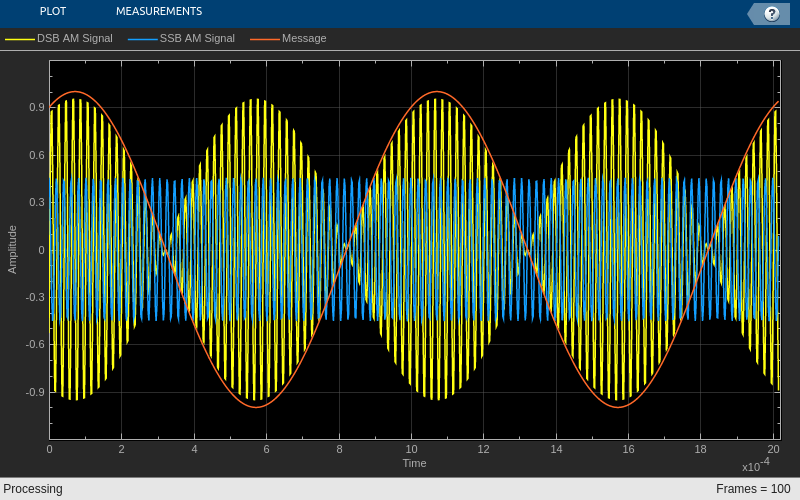

clc; clear; close all;
addpath('matlab/SSB_SC');

FrameSize = 1011;   % размер обрабатываемой за один раз пачки данных
Fs = 500e3;         % тактовая частота (Hz)

% выбор метода модуляции
ModulationMethod = "LSB";  

% генератор гармонических сигналов
% частота тона: 1 kHz
% частота несущей: 50 kHz
MessageAndCarrierGen = dsp.SineWave(...
    'SampleRate', Fs, ...
    'SamplesPerFrame', FrameSize, ...
    'Frequency', [50e3 1e3], ...
    'Amplitude', [1 1] ...
    );

% расчет коэффициентов и создание полосового фильтра
if (ModulationMethod == "USB")
    H = Transmitter_USB_FIR_Coeff_1(); 
else
    H = Transmitter_LSB_FIR_Coeff_1(); 
end
BandpassFIR = dsp.FIRFilter(H.Numerator);

% объект для отрисовки графиков
Plotter = dsp.ArrayPlot(...
    'PlotType', 'Line', ...
    'YLimits', [-1.2, 1.2], ...
    'SampleIncrement', 1/Fs, ...
    'XLabel', 'Time', ...
    'YLabel', 'Amplitude', ...
    'ChannelNames', {'DSB AM Signal','SSB AM Signal','Message'} ...
    );

% запуск симуляции
for i = 1:100
    % формирование тонального сигнала и несущей
    SineWaves = MessageAndCarrierGen();
    Carrier = SineWaves(:,1); 
    Message = SineWaves(:,2);

    % амплитудная модуляция
    DSBAmSignal = Message.*Carrier;
    
    % фильтрация для удаления второй полосы
    SSBAmSignal = BandpassFIR(DSBAmSignal);

    % вывод результатов на график
    Plotter([DSBAmSignal, SSBAmSignal, Message])

    % задержка в 0.1 секунды для лучшей визуализации
    pause(0.1)
end

На временной диаграмме можно видеть гармонический сигнал, соответствующй информационному сообщению (красный). Желтым обозначен результат умножения сообщения на несущую. Этот сигнал соответствует обычной DSB модуляции. Синим цветом представлен сигнал после фильтрации полосовым фильтром. Так как модуляция однотональная, этот сигнал соответсвует синусоиде, частота которой равна $f_c -f_m$ для LSB, и равна $f_c +f_m$ для USB.

Теперь рассмотрим, как эти преобразования выглядят в частотной области. Как упоминалось ранее, Такми образом, результат однотональной модуляции равен сумме двух гармонических сигналов, частоты которых равны $f_m +f_c$ и $f_c -f_m$ Гц:

$s_{\textrm{am}} \left(t\right)=\frac{A_m A_c }{2}\left\lbrack \cos \left(2\pi \left(f_m +f_c \right)t\right)+\cos \left(2\pi \left(f_c -f_m \right)t\right)\right\rbrack$.

В частотной области это соответствует спектру:

$s_{\textrm{am}} \left(t\right)\iff \frac{A_m A_c }{4}\left\lbrack \delta \left(f+f_c +f_m \right)+\delta \left(f+f_c -f_m \right)+\delta \left(f-f_c +f_m \right)+\delta \left(f-f_c -f_m \right)\right\rbrack$.

Этот результат можно получить, если вспомнить, что спектр гармонического сигнала состоит из двух дельта-функций, и произведение сигналов во временной области соответствует их свертке в частотной.

Если использовать полосовой фильтр для удаления гармонки на частоте $f_m +f_c$, то мы получим LSB сигнал, спектр которого равен:

$s_{\textrm{LSB}} \left(t\right)\iff \frac{A_m A_c }{4}\left\lbrack \delta \left(f+f_c -f_m \right)+\delta \left(f-f_c +f_m \right)\right\rbrack$.

Аналогичные результаты получаем для  USB сигнала:

$s_{\textrm{USB}} \left(t\right)\iff \frac{A_m A_c }{4}\left\lbrack \delta \left(f-f_c -f_m \right)+\delta \left(f+f_c +f_m \right)\right\rbrack$.

Ниже представлен скрипт для получения спектра одноплосного сигнала для случая однотональной модуляции. С помощью переменной ModulationMethod можно выбрать, полосовой фильтр, который сформирует USB или LSB сигнал:

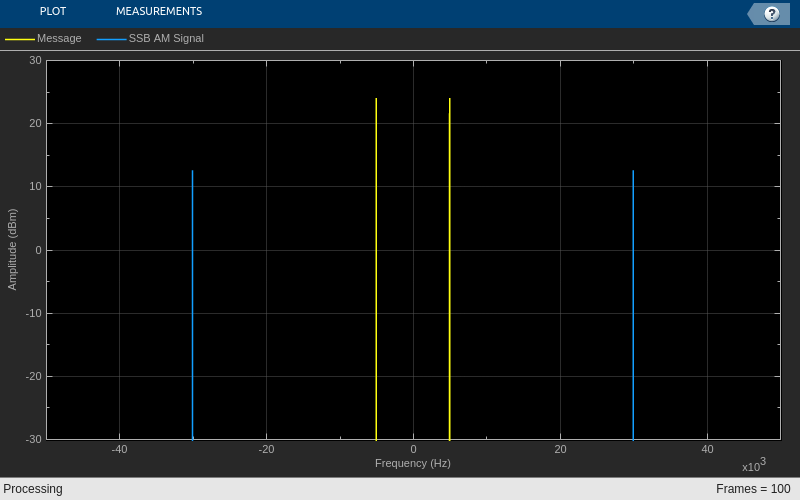

clc; clear; close all;
addpath('matlab/SSB_SC');

FrameSize = 5000;   % размер обрабатываемой за один раз пачки данных
Fs = 100e3;         % тактовая частота (Hz)

% выбор метода модуляции
ModulationMethod = "LSB"; 

% генератор гармонических сигналов
% частота тона: 5 kHz
% частота несущей: 35 kHz
MessageAndCarrierGen = dsp.SineWave(...
    'SampleRate',Fs,...
    'SamplesPerFrame',FrameSize,...
    'Frequency',[35e3 5e3],...
    'Amplitude',[1 1] ...
    );

% расчет коэффициентов и создание полосового фильтра
if (ModulationMethod == "USB")
    H = Transmitter_USB_FIR_Coeff_2(); 
else
    H = Transmitter_LSB_FIR_Coeff_2(); 
end
BandpassFIR = dsp.FIRFilter(H.Numerator);

% объект для вычисления спектра
SpecEstimator = dsp.SpectrumEstimator(...
    'PowerUnits','dBm', ...
    'FrequencyRange', 'centered', ...
    'SampleRate', Fs ...
    );

% объект для отрисовки графиков
Plotter = dsp.ArrayPlot(...
    'PlotType','Line', ...
    'XOffset', -Fs/2, ...
    'YLimits', [-30, 30], ...
    'XLabel', 'Frequency (Hz)', ...
    'YLabel', 'Amplitude (dBm)', ...
    'ChannelNames', {'Message', 'SSB AM Signal'}, ...
    'SampleIncrement', Fs/FrameSize ...
    );

% запуск симуляции
for i = 1:100
    % формирование тонального сигнала и несущей
    SineWaves = MessageAndCarrierGen();
    Carrier = SineWaves(:,1); 
    Message = SineWaves(:,2);

    % амплитудная модуляция
    DSBAmSignal = Message.*Carrier;

    % фильтрация для удаления второй полосы
    SSBAmSignal = BandpassFIR(DSBAmSignal);
    
    % вычисление спектров
    Spectrums = SpecEstimator([Message, SSBAmSignal]);
    
    % вывод результатов на график
    Plotter(Spectrums)
    
    % задержка в 0.1 секунды для лучшей визуализации
    pause(0.1)
end

На графике представлен спектр информационного сигнала (желтый) и спектр однополосного сигнала (синий). Можно увидеть, что модулированный сигнал состоит из двух дельта-функций, что подтвеждает предыдущие рассуждения.

### 3. Однотональная модуляция с использованием преобразования Гильберта

Применение полосовых фильтров для удаление части спектра сопряжено с рядом сложностей. Во-первых, в зависимости от спектра информационного сообщения может потребоваться фильтр с очень узкой переходной полосой. Такой фильтр потребует очень много коэффициентов, что увиличивает вычислительные затраты на обработку сигнала.  Во-вторых, фильтрация выполняется на последнем этапе формирования сигнала на повышенной частоте дискретизации. В-третьих, при изменении частоты несущей коэффициенты фильтра также необходимо будет пересчитывать.

В связи с представленными недостатками, как правило, на практике однополосный сигнал формируется другим способом, основанным на преобразовании Гильберта. Рассмотрим из-за чего происходит удвоение полосы сигнала при обычной модуляции. Любой действительный сигнал имеет симметричный спектр относительно нулевой частоты. Как правило, спектр информационного сообщения распологается около нулевой частоты, поэтому такой сигнал называют Base Band. При умножении сообщения на гармонический сигнал его спектр переносится на частоту несущей. На это частоты переносятся компоненты спектра как из положительной, так и из отрицательной области частот. Так как спектр симметричный ширина спектра Base Band сигнала на положительных и отрицательных частотах совпадает, поэтому после переноса на несущую ширина спектра удваивается.

Удвоение спектра можно избежать, если удалить компоненты спектра сообщения на отрицательных частотах. Так как при этом спектра станет несимметричным, сообщение будет комплексным, и такой сигнал называют аналитическим. Аналитический сигнал можно получить с помощью преобразования Гильберта, которое представляет из себя всепропускающий фильтр, который изменяет только фазу сигнала. Преобразование Гильберта формирует мнимую часть аналитического сигнала. Таким образом, можем записать:


$$m_A \left(t\right)=m\left(t\right)+j\cdot m_H \left(t\right),$$


где $m\left(t\right)$ - исходное информационное сообщение, $m_H \left(t\right)=H\left\lbrace m\left(t\right)\right\rbrace$ - преобразование Гильберта от сообщения, $m_A \left(t\right)$ - аналитический сигнал с односторонним спектром.

Этот аналитический сигнал можно перенести на несущую частоте с помощью умножения на комплексную экспоненту. В результате сигнал останется комплексным, чтобы сделать его дествительным нужно оставить только его действительную часть. В результате получим USB, так как на несущею будет перенесены положительные частоты. В виде формул данные преобразования можно записать так:

$s_{\textrm{USB}} \left(t\right)=\textrm{Real}\left\lbrace m_A \left(t\right)\cdot e^{j\cdot 2\pi \cdot f_c \cdot t} \right\rbrace$.

Структурная схема передатчика предсталена ниже:

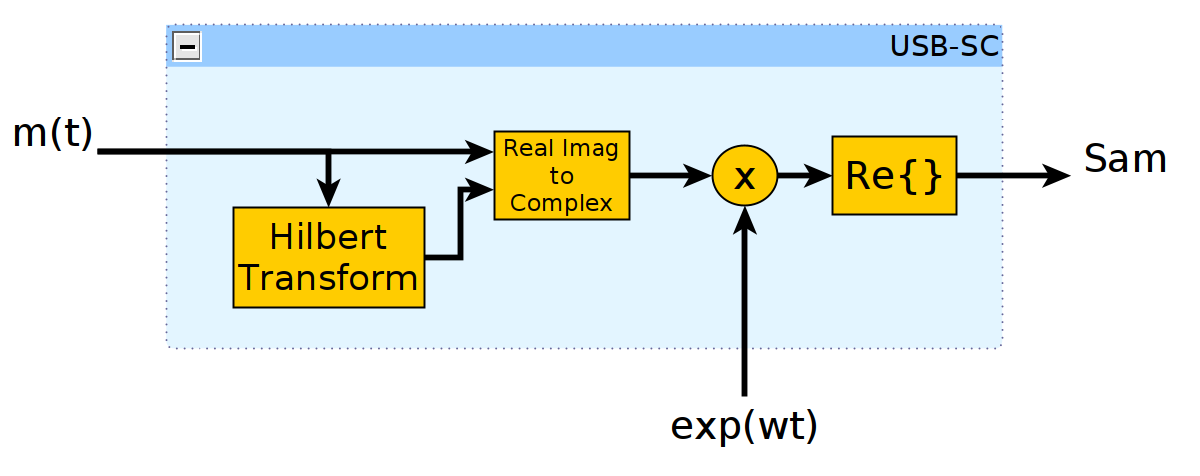

Если представить комплексную экспонету и аналитический сигнал как суммы действительной и мнимой части, то выражение для $s_{\textrm{USB}} \left(t\right)$ можно переписать в виде:


$$s_{\textrm{USB}} \left(t\right)=\textrm{Real}\left\lbrace \left(m\left(t\right)+j\cdot m_H \left(t\right),\right)\cdot \left(\cos \left(2\pi \cdot f_c \cdot t\right)+j\cdot \sin \left(2\pi \cdot f_c \cdot t\right)\right)\right\rbrace =$$



$$=\textrm{Real}\left\lbrace \left(m\left(t\right)\cdot \cos \left(2\pi \cdot f_c \cdot t\right)-m_H \left(t\right)\cdot \sin \left(2\pi \cdot f_c \cdot t\right)\right)+j\cdot \left(m_H \left(t\right)\cdot \cos \left(2\pi \cdot f_c \cdot t\right)+m\left(t\right)\cdot \sin \left(2\pi \cdot f_c \cdot t\right)\right)\right\rbrace =$$


$=m\left(t\right)\cdot \cos \left(2\pi \cdot f_c \cdot t\right)-m_H \left(t\right)\cdot \sin \left(2\pi \cdot f_c \cdot t\right)$.

Таким образом, схему приемника можно представить в виде:

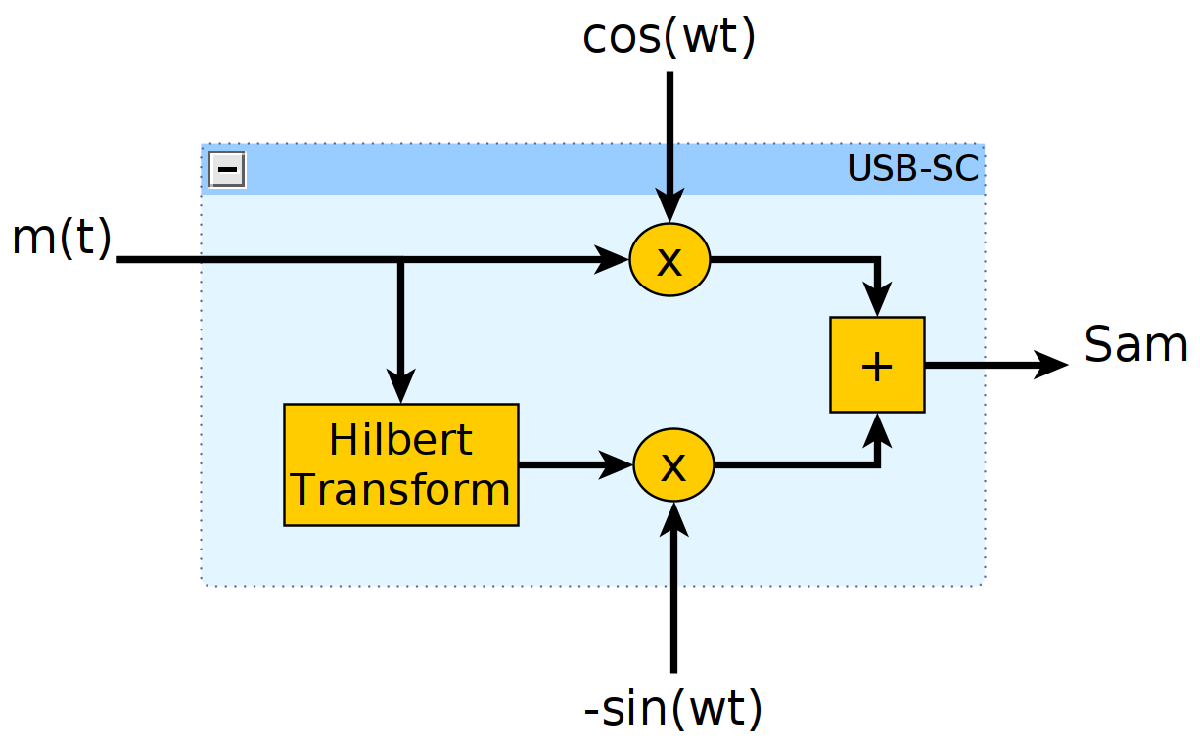

Если провести комплексное сопряжение аналитического сигнала, то получим сигнал, который содержит только отрицательные частоты. После переноса на несущую частоту и выделения действительной части получим LSB сигнал. То есть, имеем:

$s_{\textrm{LSB}} \left(t\right)=\textrm{Real}\left\lbrace m_A^* \left(t\right)\cdot e^{j\cdot 2\pi \cdot f_c \cdot t} \right\rbrace$.

Структурная схема передатчика предсталена ниже:

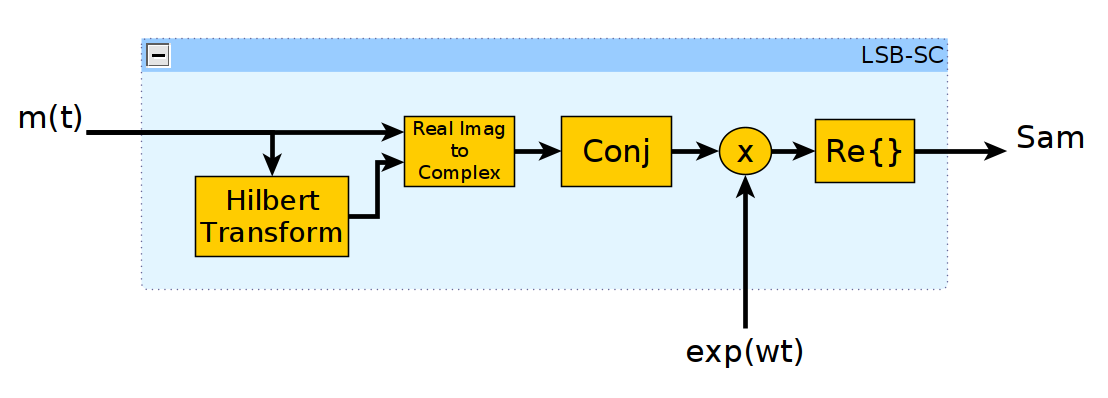

Если представить комплексную экспонету и аналитический сигнал как суммы действительной и мнимой части, то выражение для $s_{\textrm{LSB}} \left(t\right)$ можно переписать в виде:

$s_{\textrm{LSB}} \left(t\right)=m\left(t\right)\cdot \cos \left(2\pi \cdot f_c \cdot t\right)+m_H \left(t\right)\cdot \sin \left(2\pi \cdot f_c \cdot t\right)$.

Таким образом, схему приемника можно представить в виде:

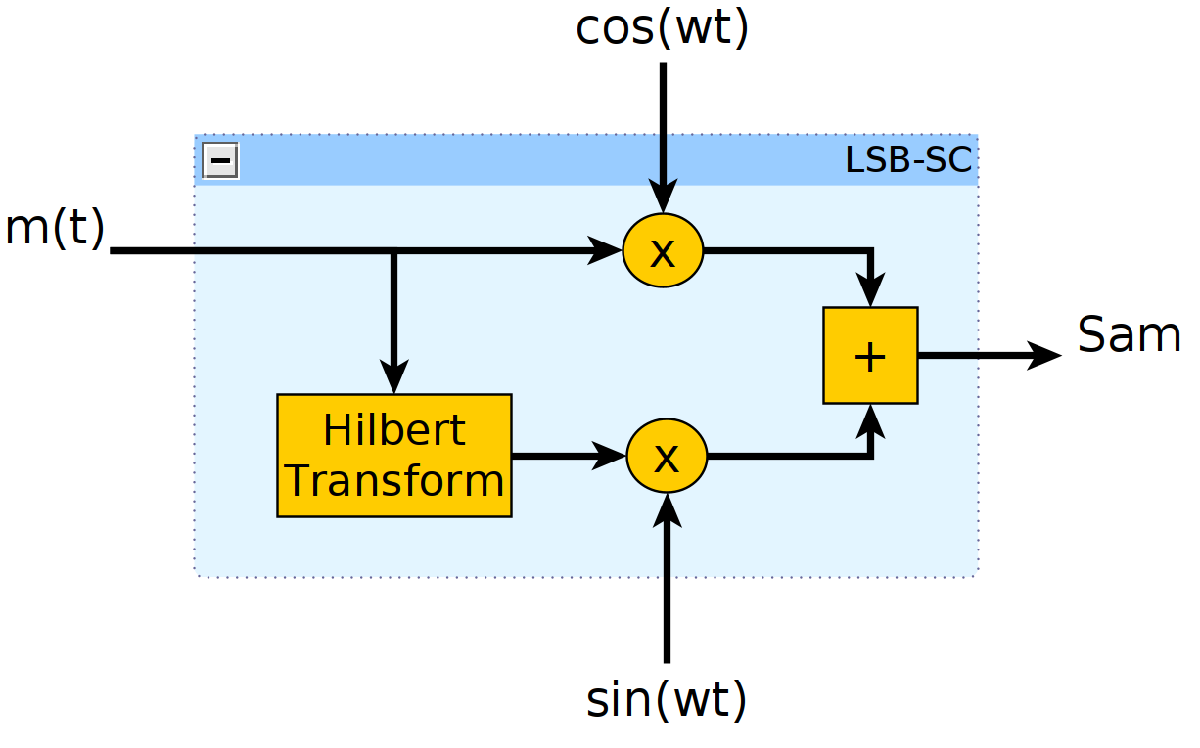

Рассмотрим данный метод формирования однополосного сигнала для случая однотональной модуляции. В этом случае информационное сообщение представляет из себя гармонический сигнал вида: 

$m\left(t\right)=A_m \cos \left(2\pi f_m t\right)$,

где $A_m$ - амплитуда тона, $f_m$ - частота в герцах. 

Преобразование Гильберта от косинуса равно синусу той же частоты. Значит можем записать:


$$m_H \left(t\right)=A_m \sin \left(2\pi f_m t\right)\ldotp$$


Таким образом, аналитичечкий сигнал можно представить в виде:


$$m_A \left(t\right)=m\left(t\right)+j\cdot m_H \left(t\right)=A_m \cos \left(2\pi f_m t\right)+j\cdot A_m \sin \left(2\pi f_m t\right)=A_m \cdot e^{j\cdot 2\pi \cdot f_m \cdot t} \ldotp$$


После переноса на несущую частоту с помощью умножения на комплексную экспоненту и взятия действительной части получим:


$$s_{\textrm{USB}} \left(t\right)=\textrm{Real}\left\lbrace A_m \cdot e^{j\cdot 2\pi \cdot f_m \cdot t} \cdot e^{j\cdot 2\pi \cdot f_c \cdot t} \right\rbrace =\textrm{Real}\left\lbrace A_m \cdot e^{j\cdot 2\pi \cdot \left(f_m +f_c \right)\cdot t} \right\rbrace =A_m \cos \left(2\pi \left(f_c +f_m \right)t\right)\ldotp$$


То есть, как и ожидалось, USB сигнал для однотонального случая состоит из единственного тона на частоте $f_c +f_m$. 

Чтобы получить LSB сигнал, необходиму предварительно произвести комплексное сопряжение аналитического сигнала. В связи с этим можем записать:


$$m_A^* \left(t\right)=A_m \cdot e^{-j\cdot 2\pi \cdot f_m \cdot t} \ldotp$$



$$s_{\textrm{LSB}} \left(t\right)=\textrm{Real}\left\lbrace A_m \cdot e^{-j\cdot 2\pi \cdot f_m \cdot t} \cdot e^{j\cdot 2\pi \cdot f_c \cdot t} \right\rbrace =\textrm{Real}\left\lbrace A_m \cdot e^{j\cdot 2\pi \cdot \left(f_c -f_m \right)\cdot t} \right\rbrace =A_m \cos \left(2\pi \left(f_c -f_m \right)t\right)\ldotp$$


То есть, LSB сигнал для однотонального случая состоит из единственного тона на частоте $f_c -f_m$. 

Ниже представлен скрипт для получения спектра одноплосного сигнала с помощью преобразования Гильберта для случая однотональной модуляции. С помощью переменной ModulationMethod можно выбрать, полосовой фильтр, который сформирует USB или LSB сигнал:

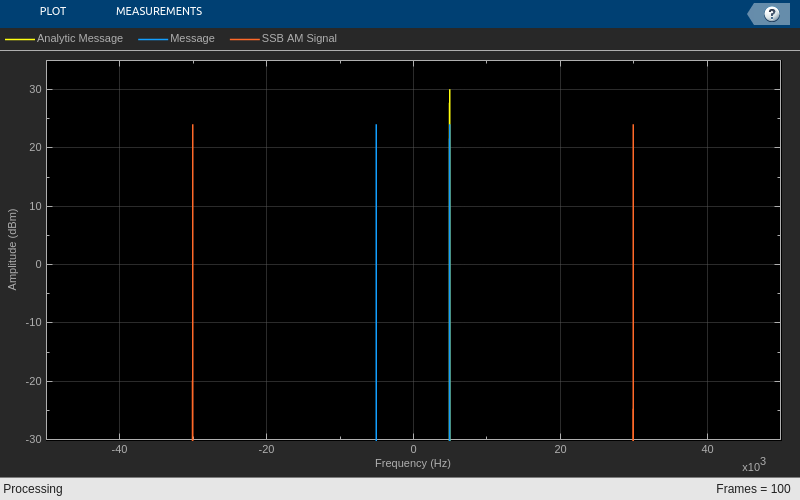

clc; clear; close all;
addpath('matlab/SSB_SC');

FrameSize = 5000;   % размер обрабатываемой за один раз пачки данных
Fs = 100e3;         % тактовая частота (Hz)

% выбор метода модуляции
ModulationMethod = "LSB"; 

% генератор однотонального сигнала
% частота тона: 5 kHz
Message = dsp.SineWave(...
    'SampleRate',Fs,...
    'SamplesPerFrame',FrameSize,...
    'Frequency', 5e3,...
    'Amplitude', 1 ...
    );

% генератор несущей
% частота несущей: 35 kHz
Carrier = dsp.SineWave(...
    'SampleRate', Fs,...
    'SamplesPerFrame', FrameSize,...
    'Frequency', 35e3,...
    'ComplexOutput', true, ...
    'Amplitude', 1);

% формирует аналитический сигнал
HilbertTranform = dsp.AnalyticSignal(...
    'FilterOrder', 100 ...
    );

% объект для вычисления спектра
SpecEstimator = dsp.SpectrumEstimator(...
    'PowerUnits','dBm', ...
    'FrequencyRange', 'centered', ...
    'SampleRate', Fs ...
    );

% объект для отрисовки графиков
Plotter = dsp.ArrayPlot(...
    'PlotType','Line', ...
    'XOffset', -Fs/2, ...
    'YLimits', [-30, 35], ...
    'XLabel', 'Frequency (Hz)', ...
    'YLabel', 'Amplitude (dBm)', ...
    'ChannelNames', {'Analytic Message', 'Message', 'SSB AM Signal'}, ...
    'SampleIncrement', Fs/FrameSize ...
    );

% запуск симуляции
for i = 1:100
    % формирование тонального сигнала
    MessageData = Message();

    % формирование аналитического сигнала
    AnalyticData = HilbertTranform(MessageData);
    
    % формирование несущей
    CarrierWave = Carrier(); 

    % однополосная модуляция модуляция
    if (ModulationMethod == "USB")
        SSBAmSignal = real(AnalyticData.*CarrierWave);
    else
        SSBAmSignal = real(conj(AnalyticData).*CarrierWave);
    end
    
    % вычисление спектров
    Spectrums = SpecEstimator([AnalyticData, MessageData, SSBAmSignal]);
    
    % вывод результатов на график
    Plotter(Spectrums)
    
    % задержка в 0.1 секунды для лучшей визуализации
    pause(0.1)
end

На графике представлен спектр информационного сигнала (синий) и спектр аналитического сигнала (желтый). В зависимости от вида модуляции (USB или LSB) аналитеческий сигнал будет располагаться только на положительных или только на отрицательных частотах. Также можно увидеть, что модулированный сигнал состоит из двух дельта-функций, что совпадает с предыдущими результатами, полученными с помощью полосового фильтра.

### 4. Модуляция несколькими тонами

Разобравшись с однотональной модуляцией, легко распространить результаты на случай модуляции несколькими тонами. Пусть информационный сигнал представляет из себя сумму гармонических сигналов:

$m\left(t\right)=\sum_{i=1}^N A_i \cos \left(2\pi f_i t\right)$,

Рассмотрим, что происходит в частотной области. В случае обычной DSB модуляции несколькими тонами модулированный сигнал примет следующий вид:  

$s_{\textrm{am}} \left(t\right)=\sum_{i=1}^N A_i \cos \left(2\pi f_i t\right)\cdot A_c \cos \left(2\pi f_c t\right)=\frac{A_c }{2}\sum_{i=1}^N A_i \left\lbrack \cos \left(2\pi \left(f_i +f_c \right)t\right)+\cos \left(2\pi \left(f_i -f_c \right)t\right)\right\rbrack$.

То есть после модуляции каждому тону будут соответстовать две гармоники на частотах $f_i +f_c$ и $f_i -f_c$. Как упоминалось ранее начилие двух тонов приводит к удвоению спетра. С помощью прелсталеннх выше схем передатчиков можно удалить верхниюю или нижнюю половину спектров. Построим спектры сигналов для случая модуляции тремя тонами.

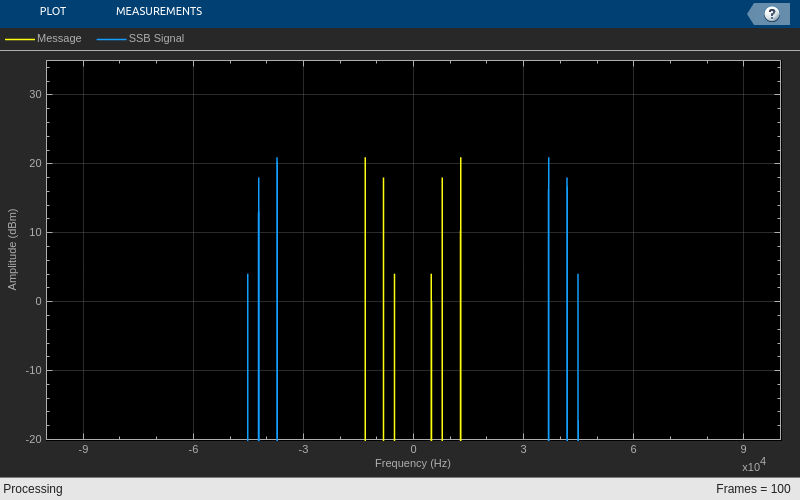

clc; clear; close all;

FrameSize = 5000;   % размер обрабатываемой за один раз пачки данных
Fs = 200e3;         % тактовая частота (Hz)

% выбор метода модуляции
ModulationMethod = "LSB"; 

% генератор информационного сигнала из трех тонов
% частота тонов: 5, 8 и 13 kHz
% амплитуды тонов: 0.1, 0.5 и 0.7
Message = dsp.SineWave(...
    'SampleRate', Fs,...
    'SamplesPerFrame', FrameSize,...
    'Frequency', [5e3 8e3 13e3],...
    'Amplitude', [0.1 0.5 0.7]);

% генератор несущей
% частота несущей: 35 kHz
Carrier = dsp.SineWave(...
    'SampleRate', Fs,...
    'SamplesPerFrame', FrameSize,...
    'Frequency', 50e3,...
    'ComplexOutput', true, ...
    'Amplitude', 1);

% формирует аналитический сигнал
HilbertTranform = dsp.AnalyticSignal(...
    'FilterOrder', 100 ...
    );

% объект для вычисления спектра
SpecEstimator = dsp.SpectrumEstimator(...
    'PowerUnits','dBm',...
    'FrequencyRange','centered',...
    'SampleRate',Fs ...
    );

% объект для отрисовки графиков
Plotter = dsp.ArrayPlot(...
    'PlotType','Line', ...
    'XOffset', -Fs/2, ...
    'YLimits', [-20, 35], ...
    'XLabel', 'Frequency (Hz)', ...
    'YLabel', 'Amplitude (dBm)', ...
    'ChannelNames', {'Message', 'SSB Signal'}, ...
    'SampleIncrement', Fs/FrameSize ...
    );

% запуск симуляции
for i = 1:100
    % формирование информационного сигнала
    MessageData = Message();
    MessageData = MessageData(:,1) + MessageData(:,2) + MessageData(:,3);

    % формирование аналитического сигнала
    AnalyticData = HilbertTranform(MessageData);
    
    % формирование несущей
    CarrierWave = Carrier(); 

    % однополосная модуляция модуляция
    if (ModulationMethod == "USB")
        SSBAmSignal = real(AnalyticData.*CarrierWave);
    else
        SSBAmSignal = real(conj(AnalyticData).*CarrierWave);
    end
    
    % вычисление спектров
    Spectrums = SpecEstimator([MessageData, SSBAmSignal]);
    
    % вывод результатов на график
    Plotter(Spectrums)
    
    % задержка в 0.1 секунды для лучшей визуализации
    pause(0.1)
end

Можно увидеть, что спектр модулированного сигнала (синий) в зависимости от вида модуляции соответсвует  верхней или нижней половины спектра информационного сообщения (желтый).

### 5. Модуляция звуковым сигналом

Рассмотрим, как будет выглядеть спектр сигнала после однополосной модуляции, если информационное сообщение является аудиосигналом. В файле Audio_Source.wav записано звуковое сообщение с частотой дискретизации 44.1 kHz. Частота несущей будет равна 60 kHz. Чтобы избежать наложения спектров, выберем итоговую частоту дискретизации модулированного сигнала в 5 раз больше частоты аудиосигнала, то есть 5 * 44.1 kHz. Это потребует провести интерполяцию для увеличения частоты дискретизации информационного сообщения.

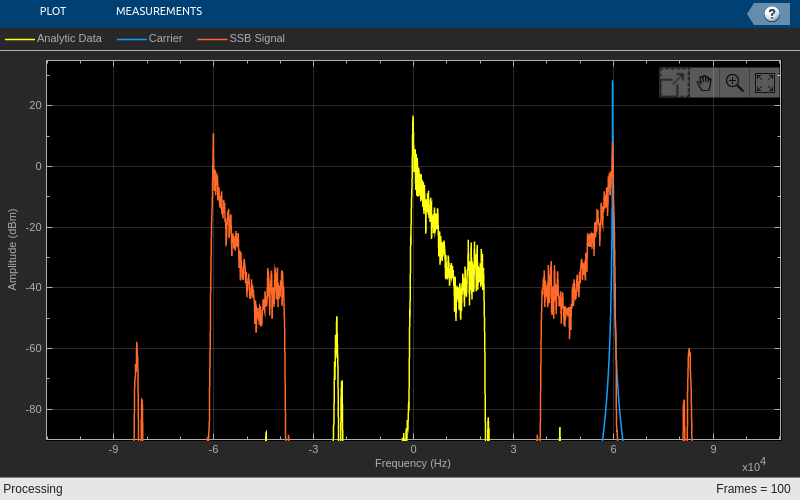

clc; clear; close all;

AudioFrameSize = 1000;  % количество отсчетов аудиофайла, получаемых за один раз
FramesNumber = 100;     % число обрабатываемых пачек данных
RateRatio = 5;          % коэффициент увеличения частоты дискретизации

% выбор метода модуляции
ModulationMethod = "LSB"; 

% объект для считываения отсчетов аудиофайла
AudioReader = dsp.AudioFileReader(...
    'wav/Audio_Source.wav', ...
    'SamplesPerFrame',AudioFrameSize...
    );

% дополнительные расчеты
AudioFs = AudioReader.SampleRate;               % получаем частоту дискретизации аудиосообщения
SignalFs = AudioFs * RateRatio;                 % частота дискретизации модулированного сигнала
SignalFrameSize = AudioFrameSize * RateRatio;   % количество отсчетов Ам-сигнала, получаемых за один раз

% генератор несущей с частотой 60 kHz
Carrier = dsp.SineWave(...
    'SampleRate', SignalFs,...
    'SamplesPerFrame', SignalFrameSize,...
    'Frequency', 60e3,...
    'ComplexOutput', true, ...
    'Amplitude', 1);

% объект вычисления преобразования Гильберта
% формирует аналитический сигнал
HilbertTranform = dsp.AnalyticSignal(...
    'FilterOrder', 100 ...
    );

% интерполятор 
Upsampler = dsp.SampleRateConverter(...
    'Bandwidth', 40e3, ...
    'InputSampleRate',AudioFs, ...
    'OutputSampleRate', SignalFs ...
    );

% объект для вычисления спектра
SpecEstimator = dsp.SpectrumEstimator(...
    'PowerUnits','dBm',...
    'FrequencyRange','centered',...
    'SampleRate',SignalFs);

% объект для отрисовки графиков
Plotter = dsp.ArrayPlot(...
    'PlotType','Line', ...
    'XOffset', -SignalFs/2, ...
    'YLimits', [-90, 35], ...
    'XLabel', 'Frequency (Hz)', ...
    'YLabel', 'Amplitude (dBm)', ...
    'ChannelNames', {'Analytic Data', 'Carrier', 'SSB Signal'}, ...
    'SampleIncrement', SignalFs/SignalFrameSize ...
    );

% запуск симуляции
for i = 1:FramesNumber
    % считывание отсчетов аудиосообщения и выделение одного канала из
    % стерео сигнала
    AudioData = AudioReader();
    AudioData = AudioData(:,1);
    
    % формирование аналитического сигнала
    AnalyticData = HilbertTranform(AudioData);

    % увеличение частоты дискретизации аудиосообщения
    UpsampledData = Upsampler(AnalyticData);
     
    % формирование несущей
    CarrierWave = Carrier(); 

    % однополосная модуляция модуляция
    if (ModulationMethod == "USB")
        SSBAmSignal = real(UpsampledData.*CarrierWave);
    else
        SSBAmSignal = real(conj(UpsampledData).*CarrierWave);
    end
    
    % вычисление спектров
    SpectrumData = SpecEstimator([UpsampledData, CarrierWave, SSBAmSignal]);

    % вывод результатов на график
    Plotter(SpectrumData)

    % задержка в 0.1 секунды для лучшей визуализации
    pause(0.1)
end

Можно увидеть,что в результате преобразования Гильберта удаление одной из половин спектра сообщения выполняется не идеально. На спектре видны остатки подавленной половины.  Остатки подавленного спектра могут влиять на соседние каналы. В нашем  примере, амплитуда подавленых спектральных компонентов отличается от сигнала почти на 40 дБ. В зависимости от требований к передатчику этого может быть достаточно, а может и нет.

### 6. Готовые решения Matlab

В среде Matlab есть готовая функция для выполения однополосной амплитудной модуляции: ssbmod(). Проверим ее работу. Функция принимает на вход информационный сигнал, частоту несущей, частоту дискретизации и начальную фазу несущей. Если в функцию передается строка "upper", то выполнятеся USB модуляция, иначе LSB. Основная часть скрипта совпадает со скриптом из предыдущего раздела.

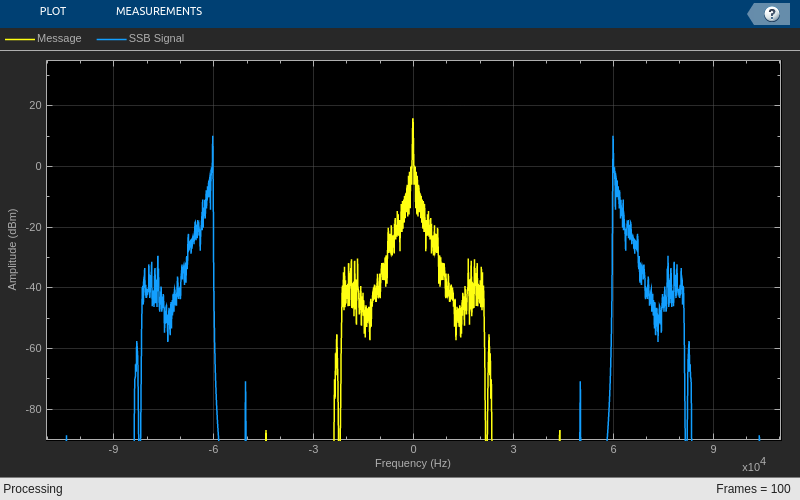

clc; clear; close all;

AudioFrameSize = 1000;  % количество отсчетов аудиофайла, получаемых за один раз
FramesNumber = 100;     % число обрабатываемых пачек данных
RateRatio = 5;          % коэффициент увеличения частоты дискретизации

CarrierPhase = 0;       % начальная фаза несущей 
CarrierFreq = 60e3;     % частота несущей

% выбор метода модуляции
ModulationMethod = "USB"; 

% объект для считываения отсчетов аудиофайла
AudioReader = dsp.AudioFileReader(...
    'wav/Audio_Source.wav', ...
    'SamplesPerFrame',AudioFrameSize...
    );

% дополнительные расчеты
AudioFs = AudioReader.SampleRate;               % получаем частоту дискретизации аудиосообщения
SignalFs = AudioFs * RateRatio;                 % частота дискретизации модулированного сигнала
SignalFrameSize = AudioFrameSize * RateRatio;   % количество отсчетов Ам-сигнала, получаемых за один раз

% интерполятор 
Upsampler = dsp.SampleRateConverter(...
    'Bandwidth', 40e3, ...
    'InputSampleRate',AudioFs, ...
    'OutputSampleRate', SignalFs ...
    );

% объект для вычисления спектра
SpecEstimator = dsp.SpectrumEstimator(...
    'PowerUnits','dBm',...
    'FrequencyRange','centered',...
    'SampleRate',SignalFs);

% объект для отрисовки графиков
Plotter = dsp.ArrayPlot(...
    'PlotType','Line', ...
    'XOffset', -SignalFs/2, ...
    'YLimits', [-90, 35], ...
    'XLabel', 'Frequency (Hz)', ...
    'YLabel', 'Amplitude (dBm)', ...
    'ChannelNames', {'Message', 'SSB Signal'}, ...
    'SampleIncrement', SignalFs/SignalFrameSize ...
    );

% запуск симуляции
for i = 1:FramesNumber
    % считывание отсчетов аудиосообщения и выделение одного канала из
    % стерео сигнала
    AudioData = AudioReader();
    AudioData = AudioData(:,1);

    % увеличение частоты дискретизации аудиосообщения
    MessageData = Upsampler(AudioData);

    % амплитудная модуляция
    if (ModulationMethod == "USB")
        AmSignal = ssbmod(MessageData, CarrierFreq, SignalFs, CarrierPhase, 'upper');
    else
        AmSignal = ssbmod(MessageData, CarrierFreq, SignalFs, CarrierPhase);
    end
    % вычисление новой фазы нусущей
    CarrierPhase = CarrierPhase + 2*pi*CarrierFreq/SignalFs*SignalFrameSize;

    % вычисление спектров
    SpectrumData = SpecEstimator([MessageData, AmSignal]);

    % вывод результатов на график
    Plotter(SpectrumData)

    % задержка в 0.1 секунды для лучшей визуализации
    pause(0.1)
end

Спектр модулированного сигнала совпадает со спектром из предыдущего пункта.

### 7. Преимущества и недостатки SSB-SC

####     Преимущества:

- уменьшение вдвое ширины спектра модулированного сигнала;

- модуляция эффективна с точки зрения мощности, так как несущая не передается.

####     Недостатки:

- возможна только когерентная демодуляция.

### Литература:

- B. P. Lathi Modern Digital and Analog Communication Systems

- R. Stewart, K. Barlee, D. Atkinson, L. Crockett Software Defined Radio using MATLAB® & Simulink and the RTL-SDR